clear
%SYSPHYS2 final project
%matrix containing all data
fulldat=readmatrix('C:\Users\hankg\OneDrive\Desktop\BME 2001 (sysphys2)\BME2002_finalproject_dataset(revised).xlsx');
%AUC for weight of each factor
results=fulldat(:,25);
full_test_dat=[results, fulldat(:,2), fulldat(:,3), fulldat(:,10), fulldat(:,11), fulldat(:,12), fulldat(:,13), fulldat(:,14), fulldat(:,15), fulldat(:,16), fulldat(:,17), fulldat(:,18)];
%all positive CKD cases
pos=full_test_dat(1:43,:);
%all negative CKD cases
neg=full_test_dat(44:end,:);
%counter
pp=0;
%cycle through each of 11 factors of note
for ii=2:12
    pp=pp+1;
    oo=0;
    %range of thresholds for each factor of note
    j=min(full_test_dat(:,ii)):(max(neg(:,ii))-min(full_test_dat(:,ii)))/100:max(neg(:,ii));
    %calculate ROC curves for each factor
    for jj=min(full_test_dat(:,ii)):(max(neg(:,ii))-min(full_test_dat(:,ii)))/100:max(neg(:,ii))
        oo=oo+1;
        tp= length(full_test_dat(full_test_dat(:,ii)>jj & full_test_dat(:,1)==1));
        tn= length(full_test_dat(full_test_dat(:,ii)<jj & full_test_dat(:,1)==0));
        fp= length(full_test_dat(full_test_dat(:,ii)>jj & full_test_dat(:,1)==0));
        fn= length(full_test_dat(full_test_dat(:,ii)<jj & full_test_dat(:,1)==1));
        sens(oo)=tp/(tp+fn);
        spec(oo)=1-tn/(fp+tn);
    end
    %find each points distance in the ROC curve to 0,1
    x=((((0-spec).^2)+((1-sens).^2)).^.5);
    %find the closest point
    y=min(x);
    z=find(x==y);
    %find the corresponding threshold to the closest point
    threshold(pp)= j(z(1));
    %finds sensitivity and specificity of best threshold for each factor
    sens_1(pp)=sens(z(1));
    spec_1(pp)=spec(z(1));
    %format sens and spec for finding area
    sens=flip(sens);
    spec=flip(spec);
    %find area under curve of each factor's ROC
    area(pp)=trapz(spec,sens);
end

%identifier numbers for each factors (each factor is assigned a number)
nn=(1:11);
%true specifity, not 1-spec which is the x value of the ROC curves
spec_1=1-spec_1;
%array that allows us to sort by AUC value
ss=[area; threshold; nn; sens_1; spec_1];
ss=ss';
%sorts array by AUC
ss=sortrows(ss)

ss = 	1.0e+03 *

    0.0000    0.0031    0.0080    0.0010         0
    0.0000    0.0513    0.0090    0.0000    0.0008
    0.0000    0.0065    0.0110    0.0000    0.0010
    0.0001    0.0010    0.0020    0.0010         0
    0.0001    0.1110    0.0060    0.0010         0
    0.0006    0.0047    0.0070    0.0005    0.0006
    0.0007    0.0800    0.0010    0.0005    0.0010
    0.0007    9.5600    0.0100    0.0006    0.0008
    0.0008    0.1274    0.0030    0.0007    0.0008
    0.0009    0.0500    0.0040    0.0008    0.0010


best_area=ss(end,1)

best_area = 0.9805

best_sens=ss(end,4)

best_sens = 0.9535

best_spec=ss(end,5)

best_spec = 1

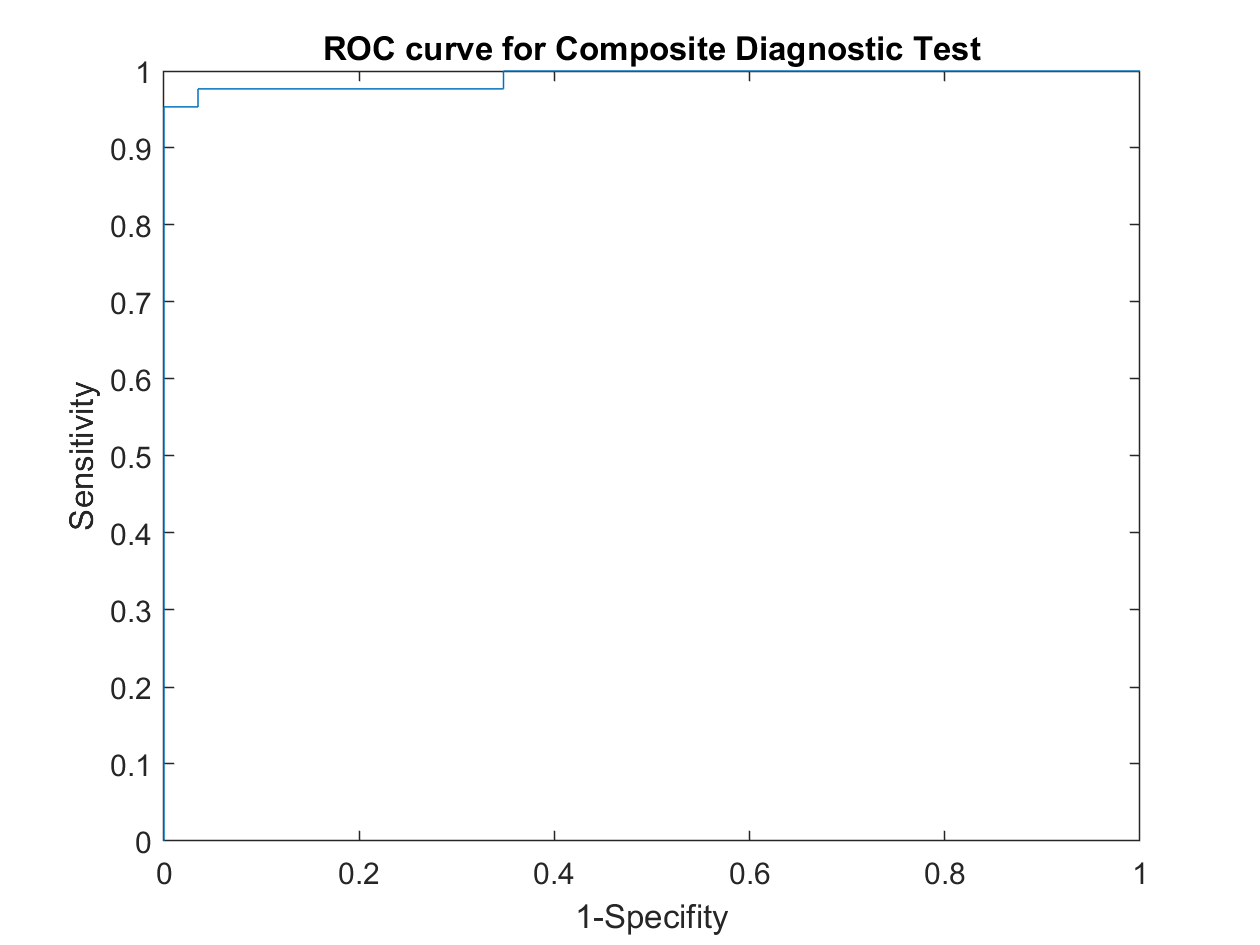

%factor with highest AUC (best indicator of CKD) (5 in column 3 = serum creatine)
ss(end,:);

%each factors identifier, corresponds to third column of ss
%1=blood pressure
%2=specific gravity
%3=blood glucose
%4=blood urea
%5=serum creatine
%6=sodium
%7=potassium
%8=hemoglobin
%9=packed cell volume
%10=white blood cell count
%11=red blood cell count

%Find new composite score for each patient integrating each factor's
%diagnostic power (determined by AUC)
u=zeros(1,158);
for ii=1:158
    %each composite score starts at 1
    u(ii)=0;
    %move through factors
    for pp=2:12
        %if threshold of factor is met, composite score increases by a
        %factor of AUC^2 of the corresponding facotr
        if full_test_dat(ii,pp)>threshold(pp-1)
        u(ii)=u(ii)+(area(pp-1))^2;
        else
            u(ii)=u(ii);
        end
    end
end

%formatting
u=u';
%put into array to test results
test_dat=[results, u];
%counter
oo=0;
%ROC curve points for composite test
for ee=min(test_dat(:,2)):(max(test_dat(:,2))-min(test_dat(:,2)))/100:max(test_dat(:,2))
   oo=oo+1;
   tp= length(test_dat(test_dat(:,2)>ee & test_dat(:,1)==1));
   tn= length(test_dat(test_dat(:,2)<ee & test_dat(:,1)==0));
   fp= length(test_dat(test_dat(:,2)>ee & test_dat(:,1)==0));
   fn= length(test_dat(test_dat(:,2)<ee & test_dat(:,1)==1));
   sens(oo)= tp/(tp+fn);
   spec(oo)= 1-tn/(fp+tn);
end
plot(spec,sens)
title('ROC curve for Composite Diagnostic Test')
xlabel('1-Specifity')
ylabel('Sensitivity')


%array of potential thresholds
j=min(test_dat(:,2)):(max(test_dat(:,2))-min(test_dat(:,2)))/100:max(test_dat(:,2));
%distance each point is to 0,1 on ROC curve
x=((((0-spec).^2)+((1-sens).^2)).^.5);
%find point closest to 0,1
y=min(x);
%find corresponding threshold for this composite score
z=find(x==y);
threshold_final= j(z(1));
%sensitivity and specificity of best possible threshold determined by ROC
%for composite score
sens_best_composite=sens(z(1))

sens_best_composite = 0.9767

spec_best_composite=1-spec(z(1))

spec_best_composite = 0.9652

%formatting for AUC
sens=flip(sens);
spec=flip(spec);
%find auc of composite test
area_composite=trapz(spec,sens)

area_composite = 0.9911